% transfer learning
clear
imds = imageDatastore("MerchData", "IncludeSubfolders",true, ...
                        "LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\Assignment 3.2 Transfer learning\MerchData\MathWorks Cap\Hat_0.jpg';
                              ' ...\Assignment 3.2 Transfer learning\MerchData\MathWorks Cap\Hat_123.jpg';
                              ' ...\Assignment 3.2 Transfer learning\MerchData\MathWorks Cap\Hat_148.jpg'
                               ... and 72 more
                              }
                     Folders: {
                              ' ...\Assignment 3 Deep Learning\Assignment 3.2 Transfer learning\MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 72 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutput

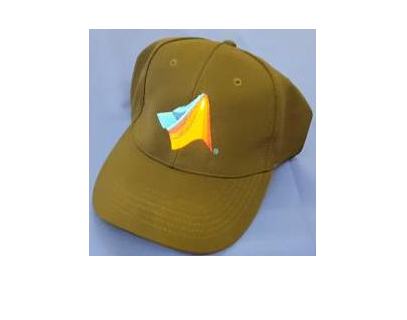


img = imread("MerchData\MathWorks Cap\Hat_0.jpg");
imshow(img)


numClasses = 5

numClasses = 5



[train, valid] = splitEachLabel(imds, 0.70, "randomize");

audsTrain = augmentedImageDatastore([227 227 3], train)

audsTrain =   augmentedImageDatastore with properties:

             NumObservations: 55
                       Files: {55×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


audsValid = augmentedImageDatastore([227 227 3], valid)

audsValid =   augmentedImageDatastore with properties:

             NumObservations: 20
                       Files: {20×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'none'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0



net = alexnet;

analyzeNetwork(net);

inputSize = net.Layers(1)

inputSize =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [227 227 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


outSize = net.Layers(end)

outSize =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'




layersTransfer = net.Layers([1:end-3])

layersTransfer =   22×1 Layer array with layers:

     1   'data'    Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0 


newFc = fullyConnectedLayer(numClasses, "WeightLearnRateFactor",20, ...
                            "BiasLearnRateFactor",20)

newFc =   FullyConnectedLayer with properties:

          Name: ''

   Hyperparameters
     InputSize: 'auto'
    OutputSize: 5

   Learnable Parameters
       Weights: []
          Bias: []

  Show all properties


newSm = softmaxLayer

newSm =   SoftmaxLayer with properties:

    Name: ''


newCl = classificationLayer

newCl =   ClassificationOutputLayer with properties:

            Name: ''
         Classes: 'auto'
      OutputSize: 'auto'

   Hyperparameters
    LossFunction: 'crossentropyex'



Layers = [layersTransfer ;newFc ;newSm ;newCl]

Layers =   25×1 Layer array with layers:

     1   'data'    Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
 



opts = trainingOptions("sgdm", "InitialLearnRate",0.0001, "MaxEpochs",6 ...
                        ,"MiniBatchSize",10, "ValidationData",audsValid ...
                        , "ValidationFrequency",3, "Plots","training-progress" ...
                        ,"Verbose",false)

opts =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-04
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 6
               MiniBatchSize: 10
                     Verbose: 0
            VerboseFrequency: 50
              ValidationData: [1×1 augmentedImageDatastore]
         ValidationFrequency: 3
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'training-progress'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddin


[MerchNet, info] = trainNetwork(audsTrain, Layers, opts)

MerchNet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


info = struct with fields:
               TrainingLoss: [1×30 double]
           TrainingAccuracy: [50 10 50 50 70 80 100 100 90 100 100 100 100 100 100 100 100 100 100 90 100 100 100 100 100 100 100 100 100 100]
             ValidationLoss: [1.7586 NaN 0.6118 NaN NaN 0.0594 NaN NaN 0.0774 NaN NaN 0.1509 NaN NaN 0.2112 NaN NaN 0.2623 NaN NaN 0.2128 NaN NaN 0.1872 NaN NaN 0.1703 NaN NaN 0.1547]
         ValidationAccuracy: [45 NaN 75 NaN NaN 100 NaN NaN 95 NaN NaN 95 NaN NaN 95 NaN NaN 95 NaN NaN 95 NaN NaN 95 NaN NaN 95 NaN NaN 95]
              BaseLearnRate: [1×30 double]
        FinalValidationLoss: 0.1547
    FinalValidationAccuracy: 95




testpreds = classify(MerchNet, audsValid)

testpreds = 20×1 categorical array
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Screwdriver 
     MathWorks Screwdriver 
     MathWorks Screwdriver 
     MathWorks Screwdriver 
     MathWorks Torch 
     MathWorks Torch 
     MathWorks Screwdriver 
     MathWorks Torch 


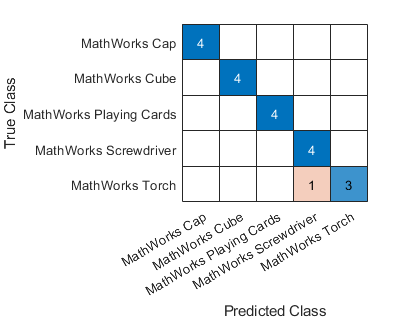


MerchActual = valid.Labels;
confusionchart(MerchActual, testpreds)

numCorrect = nnz(testpreds == MerchActual);
fracCorrect = numCorrect/20

fracCorrect = 0.9500